## Konstanten

l_b = 0.2                       %Kantenlänge Würfel

l_b = 0.2000

r_b = (l_b/2) * sqrt(2)         %Diagonale Länge durch 2

r_b = 0.1414

r_s = r_b

r_s = 0.1414

h = r_b - (l_b/2)               %Höhendifferenz Schwerpunkt

h = 0.0414


m_w = 0.05                      %Masse Rad

m_w = 0.0500

m_s = m_w

m_s = 0.0500

m_b = 0.75                      %Masse körper ohne Rad

m_b = 0.7500

m_g = m_w + m_b                 %Masse gesamt

m_g = 0.8000


r_a = 0.2/2                     %Außenradius Schwungscheibe

r_a = 0.1000

r_i = 0.15/2                    %Innenradius Schwungscheibe

r_i = 0.0750

g = 9.81                        %Gravitationskonstante

g = 9.8100


M_m = 0.3                       %Motormoment

M_m = 0.3000

M_b = 10                        %Moment der Bremse

M_b = 10

## Trägheitsmomente

Teta_w = 0.25 * m_w * (r_a^2 + r_i^2)       %Trägheitsmoment Rad leer

Teta_w = 1.9531e-04

Teta_s = 0.5 * m_s * r_a^2                  %Trägheitsmoment Scheibe gefüllt

Teta_s = 2.5000e-04

Teta_b = 1/3 * m_b * (2 * l_b^2)            %Trägheitsmoment Körper ohne Rad

Teta_b = 0.0200

Teta_g = Teta_w + Teta_b + r_b^2 * m_s      %Trägheitsmoment gesamt

Teta_g = 0.0212

## Energieerhaltung ( E_pot = E_kin )

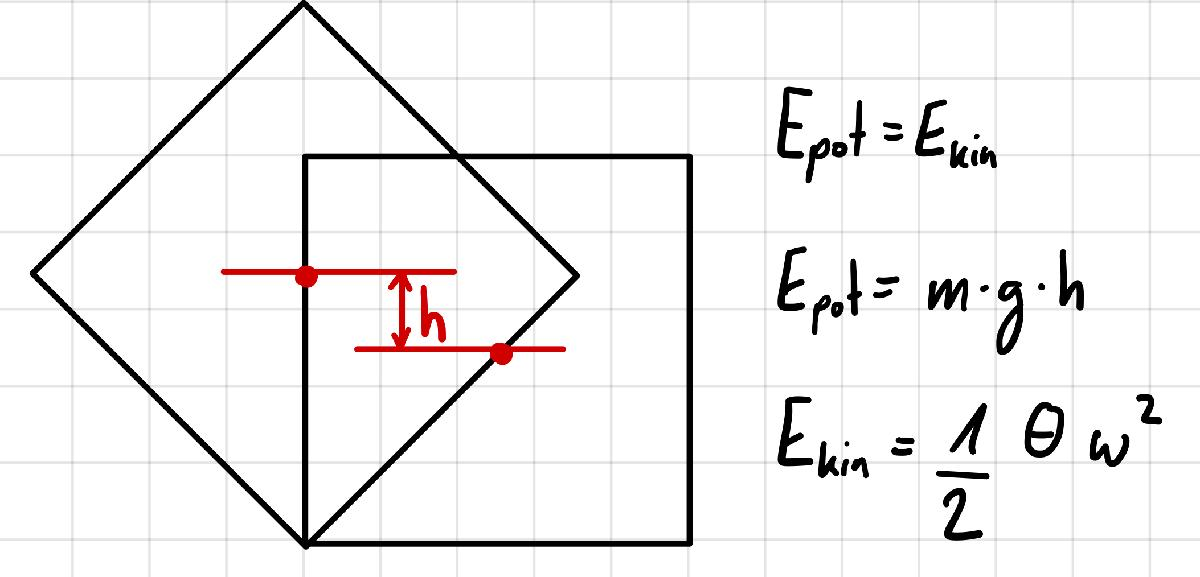

omega_g = sqrt((m_g * g * h * 2)/Teta_g)    %Drehzahl des Körpers

omega_g = 5.5384

## Drallerhaltung 

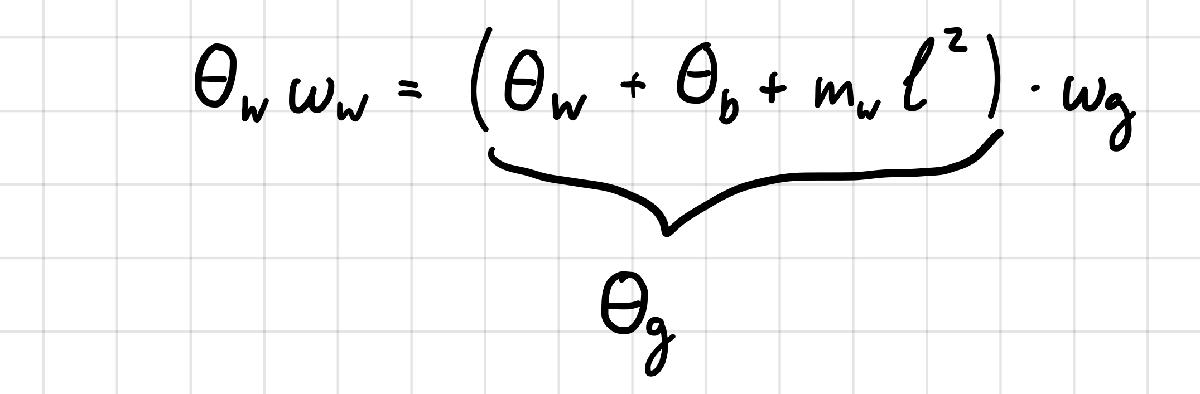

omega_rad_s = (Teta_g/Teta_s) * omega_g

omega_rad_s = 469.5551

omega_s = (1/(2 * pi)) * omega_rad_s

omega_s = 74.7320

omega_s_rpm = 60 * omega_s

omega_s_rpm = 4.4839e+03

## Drallansatz 2

Mit Gravitation. 

phi_b = pi/4                                %Startwinkel

phi_b = 0.7854

M_grav = (m_s*r_s + m_b*r_b)*g*sin(phi_b)   %Moment der Gravitation auf Punkt A

M_grav = 0.7848

0 = M_grav + omega_pp_b*Teta_b + omega_pp_s*Teta_s

omega_pp_b = 0.123 %konstanter Test Wert

omega_pp_b = 0.1230

omega_pp_s = (M_grav+omega_pp_b*Teta_b)/Teta_s

omega_pp_s = 3.1490e+03

M_b = M_grav+omega_pp_b*Teta_b

M_b = 0.7873

aus der Winkelbschleunigung der Scheibe die Torque berechnen

Torque = omega_pp_s/Teta_s

## Drallansatz ETH

## Anderes

Berechnung der Beschleunigungszeit aus dem Moment und der Zieldrehzahl

alpha = M_m/Teta_s

alpha = 1.2000e+03

t = omega_rad_s/alpha

t = 0.3913


alpha_b = M_b/Teta_s

alpha_b = 3.1490e+03

t_b = omega_rad_s/alpha_b

t_b = 0.1491

Berechnung der Drehzahl nur über die Energieerhaltung

omega_rad_s_2 = 400

omega_rad_s_2 = 400

omega_s_2 = (1/(2 * pi)) * omega_rad_s_2

omega_s_2 = 63.6620

zeit2

alpha_2 = M_m/Teta_s

alpha_2 = 1.2000e+03

t = omega_rad_s_2/alpha_2

t = 0.3333


alpha_b_2 = M_b/Teta_s

alpha_b_2 = 3.1490e+03

t_b = omega_rad_s_2/alpha_b_2

t_b = 0.1270